# Entregable Final

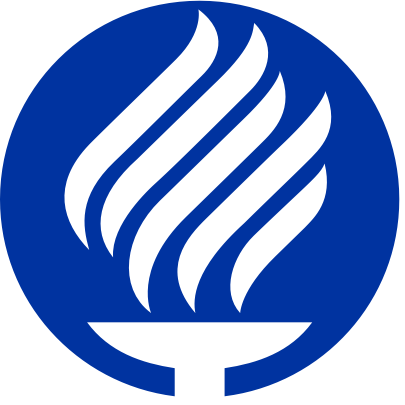

#### Tecnologico de Monterrey Campus Guadalajara 

#### Modelación computacional de sistemas eléctricos (Gpo 213)

**Juan Daniel Muñoz Dueñas**

**Hugo Alejandro Gómez Herrera **

**Iker Ochoa Villaseñor **

**Oliver Josel Hernández Rebollar**

Inicializar

clearvars
close all
clc

Placa Positiva

v = 5; % Posicion desde la cual se genera nuestro origen para las placas

dx = 30; % Separacion entre placas

heightN = 3; % Alto y ancho de las placas
anchorN = 4;

heightP = 6; % Alto y ancho de la placa positiva
anchorP = 7;

graphLimit = 75; % Limites de la zona de graficación

verticesR = [   -v ,-v, -v; % Vertice 1
                v, -v, -v;  % Vertice 2
                v, v, -v;   % Vertice 3
                -v, v, -v;  % Vertice 4
                -v, -v, v;  % Vertice 5
                v, -v, v;   % Vertice 6
                v, v, v;    % Vertice 7
                -v, v, v] .* [0.5 , heightP, anchorP] - [dx, 0 ,0]; % Vertice 8

carasR = [1 2 6 5;  % Cara 1
          2 3 7 6;  % Cara 2
          3 4 8 7;  % Cara 3
          4 8 5 1;  % Cara 4
          5 6 7 8;  % Cara 5
          1 2 3 4]; % Cara 6


Placa negativa

verticesB = [   -v ,-v, -v; % Vertice 1
                v, -v, -v;  % Vertice 2
                v, v, -v;   % Vertice 3
                -v, v, -v;  % Vertice 4
                -v, -v, v;  % Vertice 5
                v, -v, v;   % Vertice 6
                v, v, v;    % Vertice 7
                -v, v, v] .* [0.5 , heightN, anchorN] + [dx, 0 ,0]; % Vertice 8

carasB = [1 2 6 5;  % Cara 1
          2 3 7 6;  % Cara 2
          3 4 8 7;  % Cara 3
          4 8 5 1;  % Cara 4
          5 6 7 8;  % Cara 5
          1 2 3 4]; % Cara 6

paso = 20;

x0 = -graphLimit;
x1 = graphLimit;
y0 = -graphLimit;
y1 = graphLimit;
z0 = -graphLimit;
z1 = graphLimit;

[xGrid, yGrid, zGrid] = meshgrid(x0:paso:x1, y0:paso:y1, z0:paso:z1);

Se colocan los puntos de carga en las placas, se calcula el campo magnetico y se grafica con la función quiver:

k = 8.99*10^9; % Constante Electrica

Qp = 20; % Carga de la placa positiva (Coulomb)
Qn = -20; % Carga de la placa negativa (Coulomb)

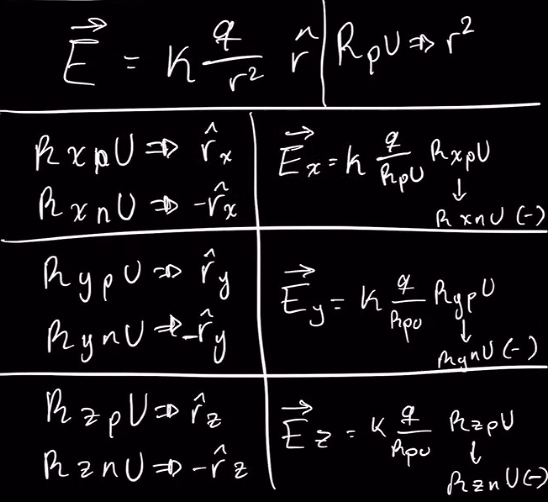

Carga -x, y, +z a  x, y, +z

RxpU = xGrid + dx; % Obtenemos todos los puntos en X
RypU = yGrid ; % Obtenemos todos los puntos en Y
RzpU = zGrid + (v * heightP); % Obtenemos todos los puntos en Z

RxnU = xGrid - dx; % Obtenemos todos los puntos en X
RynU = yGrid ; % Obtenemos todos los puntos en Y
RznU = zGrid + (v * heightN) ; % Obtenemos todos los puntos en Z

RpU = sqrt(RxpU.^2 + RypU.^2 + RzpU.^2).^2;%Se obtiene la magnitud del vector desplazamiento a traves de obtener la raiz de la suma de cuadrados 
                                           % de cada punto, para despues elevar al cuadrado de acuerdo de formula de campo electrico
                                           
RnU = sqrt(RxnU.^2 + RynU.^2 + RznU.^2).^2;

ExU = k .* Qn .* RxpU ./ RpU; % Se calcula el campo magnetico en cada punto en X
EyU = k .* Qn .* RypU ./ RpU; % Se calcula el campo magnetico en cada punto en Y
EzU = k .* Qn .* RzpU ./ RpU; % Se calcula el campo magnetico en cada punto en Z

ExU = ExU + k .* Qp .* RxnU ./ RnU; % Se calcula el campo magnetico en cada punto en X
EyU = EyU + k .* Qp .* RynU ./ RnU; % Se calcula el campo magnetico en cada punto en Y
EzU = EzU + k .* Qp .* RznU ./ RnU; % Se calcula el campo magnetico en cada punto en Y

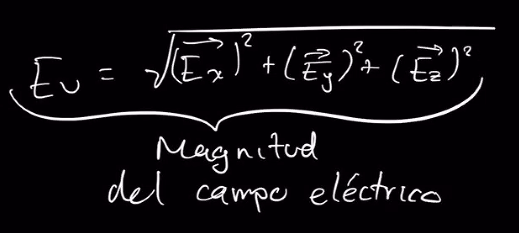

Eu = sqrt((ExU).^2 + (EyU).^2 + (EzU).^2);

iu = (ExU) ./ -Eu; % Se obtienen los componentes de el vector unitario del campo electrico superior 
ju = (EyU) ./ -Eu;
ku = (EzU) ./ -Eu;

Carga -x, y, -z a  x, y, -z

RxpD = xGrid + dx; % Obtenemos todos los puntos en X
RypD = yGrid ; % Obtenemos todos los puntos en Y
RzpD = zGrid - (v * heightP) ; % Obtenemos todos los puntos en Z

RxnD = xGrid - dx; % Obtenemos todos los puntos en X
RynD = yGrid ; % Obtenemos todos los puntos en Y
RznD = zGrid - (v * heightN) ; % Obtenemos todos los puntos en Z

RpD = sqrt(RxpD.^2 + RypD.^2 + RzpD.^2).^2;
RnD = sqrt(RxnD.^2 + RynD.^2 + RznD.^2).^2;

ExD = k .* Qn .* RxpD ./ RpD; % Se calcula el campo magnetico en cada punto en X
EyD = k .* Qn .* RypD ./ RpD; % Se calcula el campo magnetico en cada punto en Y
EzD = k .* Qn .* RzpD ./ RpD; % Se calcula el campo magnetico en cada punto en Z

ExD = ExD + k .* Qp .* RxnD ./ RnD; % Se calcula el campo magnetico en cada punto en X
EyD = EyD + k .* Qp .* RynD ./ RnD; % Se calcula el campo magnetico en cada punto en Y
EzD = EzD + k .* Qp .* RznD ./ RnD; % Se calcula el campo magnetico en cada punto en Y

Ed = sqrt((ExD).^2 + (EyD).^2 + (EzD).^2);

id = (ExD) ./ -Ed;
jd = (EyD) ./ -Ed;
kd = (EzD) ./ -Ed;

hold on

zGrid = zGrid .* 0;%Se cancelan debido a que se desea generar un plano del campo electrico, este se ubica a lo largo del eje x,y con el eje z igual a 0
ku = ku .* 0;
kd = kd .* 0;

hu = quiver3(xGrid, yGrid, zGrid, iu, ju, ku, 'color',[0 0.5 0]);
hd = quiver3(xGrid, yGrid, zGrid, id, jd, kd, 'color',[0 0.5 0]);

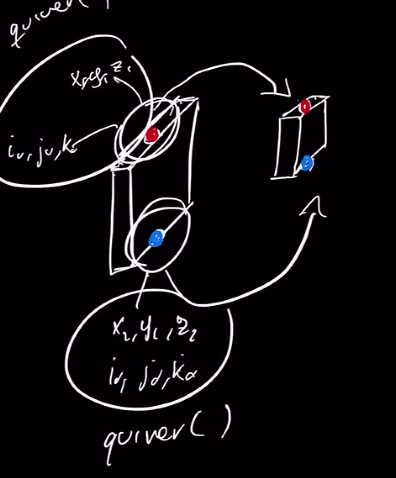

Graficacion 

patch('Faces',carasR,'Vertices',verticesR,'FaceColor','r');%Se utiliza para unir todos los bordes de las placas
patch('Faces',carasB,'Vertices',verticesB,'FaceColor','b');
view(-10,60)
axis([-graphLimit,graphLimit,-graphLimit,graphLimit,-graphLimit,graphLimit])
grid on 
Emin = esferaManual(0)

ECp = 4.4950e+10

ECn = 4.4950e+10

Emin = 8.9900e+10

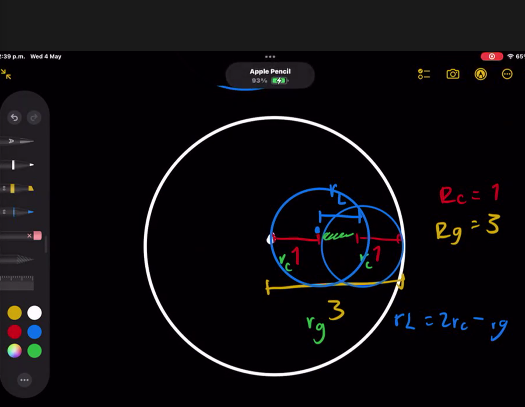

Emax = esferaManual(1)

ECp = 2.2475e+10

ECn = 2.2475e+10

Emax = 4.4950e+10


Eprom = (Emin + Emax)/2

Eprom = 6.7425e+10

Se general los 5 globulos

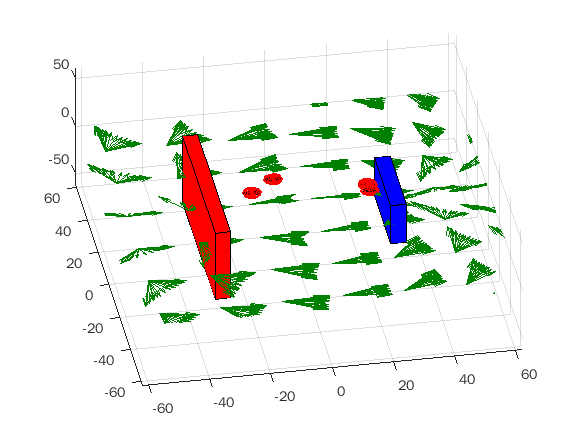

El numero de globulos infectados es: 3.000000
El paciente esta infectado de malaria



esfera(Eprom);